# MAT 275  - Lab 6                                                    Bo-Chang, Lin   

## Forced Equations and Resonance

## 
$$m\cdot x\prime \prime +c\cdot x\prime +k\cdot x=F_{0\;} \cos \left(\omega t\right)$$
    

# Exercise 1

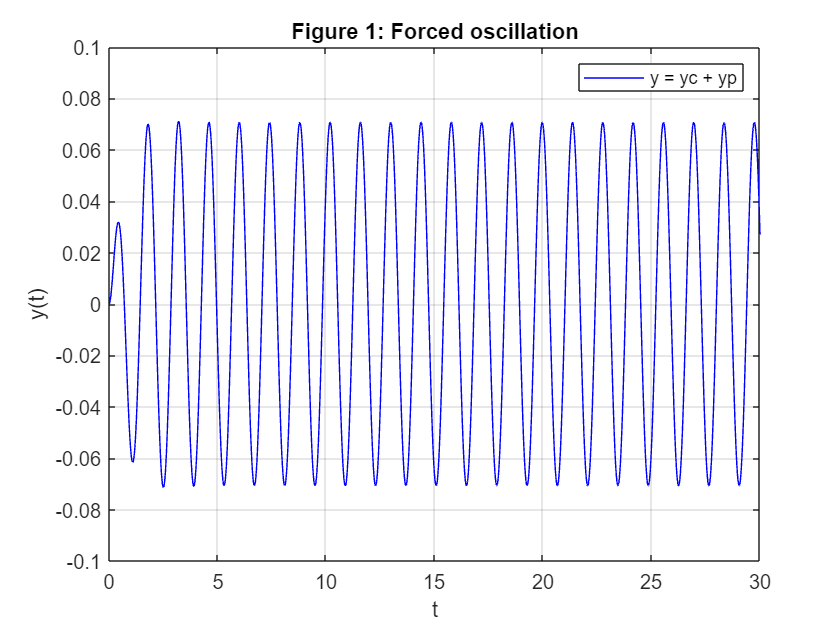

Computed amplitude of forced oscillation = 0.070655
Theoretical amplitude = 0.070656


LAB06ex1

### Part (a)

% Graphically - finding the average time interval between each peaks
[~, i]=findpeaks(y); format short    % locate peaks
T = [t(i); 0]-[0; t(i)];             % calculate time intervals (periods)
T = mean(T(2:end-1))                 % remove first and last data

T = 1.3957

T = mean(diff(t(i)))                 % or using diff() : Differences/Derivatives

T = 1.3957

% Analytically - Period: T = 2*pi/omega
T = 2*pi/omega

T = 1.3963

The period of the forced oscillation is about 1.4 second.

alpha = pi + atan(c*omega/(omega0^2-omega^2))    % w0 < w

alpha = 1.8758

The numerical value of the angle $\alpha$ is 1.8758 (rad).

### Part (b)

type LAB06ex1_b.m

clear all;  
omega0 = 4; c = 3; omega = 4.5; 
param = [omega0,c,omega]; 
t0 = 0; y0 = 0; v0 = 0; Y0 = [y0;v0]; tf = 30;
options = odeset('AbsTol',1e-10,'relTol',1e-10); 
[t,Y] = ode45(@f,[t0,tf],Y0,options,param); 
y = Y(:,1); v = Y(:,2); 

alpha = pi + atan(c*omega/(omega0^2-omega^2));         % w0 < w
Ctheory = 1/sqrt((omega0^2-omega^2)^2+(c*omega)^2);    % c < 2w0
yc = y - Ctheory*cos(omega*t-alpha);

figure 
plot(t,yc,'b-',LineWidth=1.5); 
xlabel('t'); ylabel('y(t)'); grid on; 
ylim([-.04 .03]); hold on; plot(t,0.07065*exp(-3*t/2),'r:',t,-0.07065*exp(-3*t/2),'r:')
title("The Complementary Solution: yc"); legend("yc","+/- 0.07065*exp(-3t/2)")


%----------------------------------------------------------------
function dYdt = f(t,Y,param) 
y = Y(1); v = Y(2); 
omega0 = param(1); c = param(2); omega = param(3);
dYdt = [ v ; cos(omega*t)-omega0^2*y-c*v ];
end


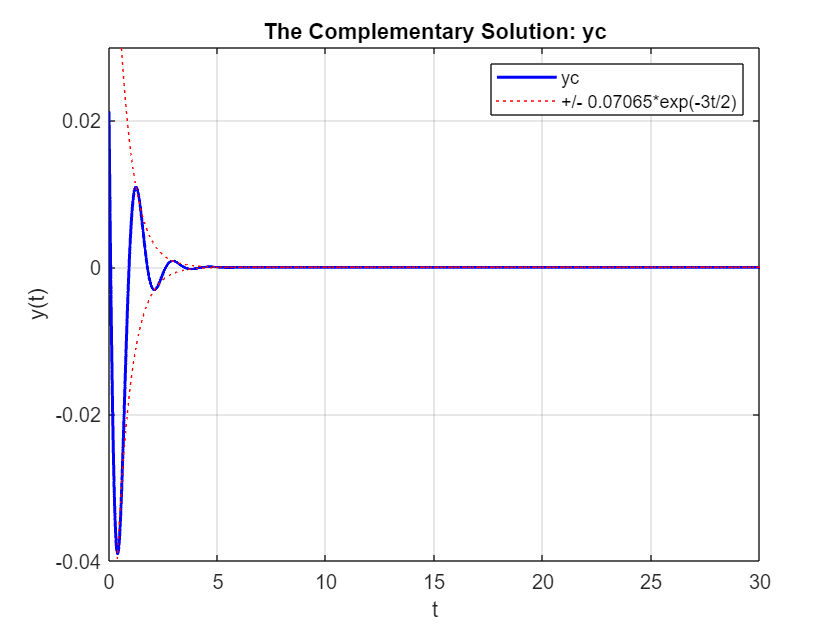

LAB06ex1_b

It dose look like an exponentially decreasing oscillation. The complementary solution represents the natural behavior of the system in the absence of the external force.

% For reference
syms y(t)
ode = diff(y,2)+3*diff(y)+16*y == cos(4.5*t);
dy = diff(y,t); cond = [y(0) == 0; dy(0) == 0];
ySol(t) = dsolve(ode,cond); ySol = simplify(ySol)

$$ySol(t) = \frac{216\,\sin\left(\frac{9\,t}{2}\right)}{3205}-\frac{68\,\cos\left(\frac{9\,t}{2}\right)}{3205}+\frac{68\,{\mathrm{e}}^{-\frac{3\,t}{2}}\,\cos\left(\frac{\sqrt{55}\,t}{2}\right)}{3205}-\frac{348\,\sqrt{55}\,{\mathrm{e}}^{-\frac{3\,t}{2}}\,\sin\left(\frac{\sqrt{55}\,t}{2}\right)}{35255}$$

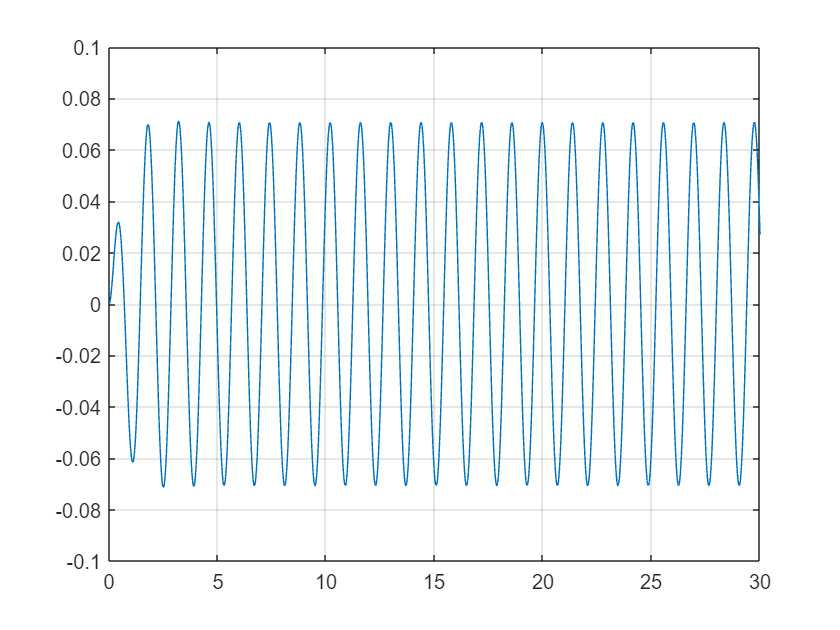

figure; fplot(ySol,[0 30]); ylim([-.1 .1]); grid on

yc = subs(subs(ySol,sin(9*t/2),0),cos(9*t/2),0)

$$yc(t) = \frac{68\,{\mathrm{e}}^{-\frac{3\,t}{2}}\,\cos\left(\frac{\sqrt{55}\,t}{2}\right)}{3205}-\frac{348\,\sqrt{55}\,{\mathrm{e}}^{-\frac{3\,t}{2}}\,\sin\left(\frac{\sqrt{55}\,t}{2}\right)}{35255}$$

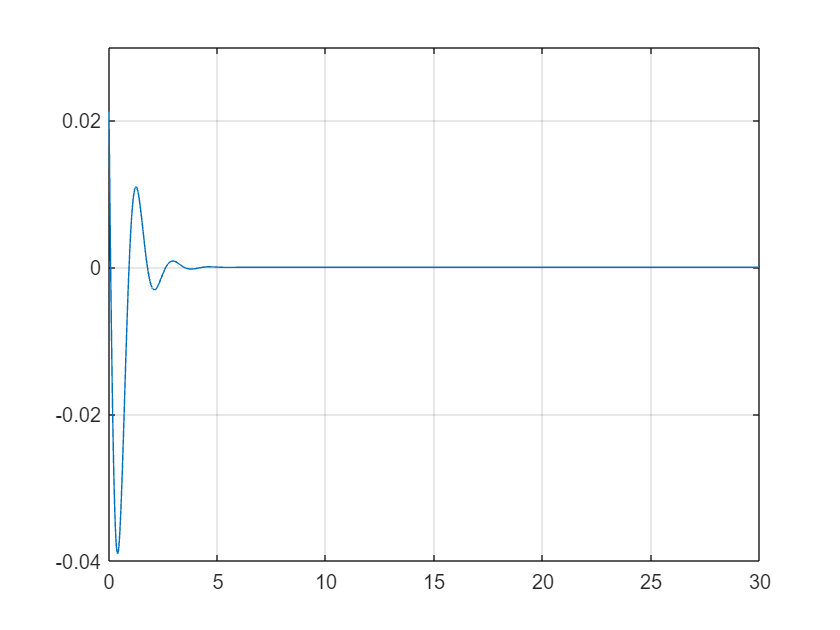

figure; fplot(yc,[0 30]); ylim([-.04 .03]); grid on

# Exercise 2

### Part (a)

***NOTE: ****Fill in the missing parts in LAB06ex2.m. Then print it and run it. Delete this note upon submission.*

type LAB06ex2.m

clear all;
omega0 = 4; c = 3;
OMEGA =2:0.01:5;
C = zeros(size(OMEGA));
Ctheory = zeros(size(OMEGA)); 
t0 = 0; y0 = 0; v0 = 0; Y0 = [y0;v0]; tf =30; t1 = 9;

for k = 1:length(OMEGA)
   omega = OMEGA(k);
   param = [omega0,c,omega];
   [t,Y] = ode45(@f,[t0,tf],Y0,[],param); 
   i = find(t>t1); 
   C(k) = (max(Y(i,1))-min(Y(i,1)))/2; 
   Ctheory(k) = 1/sqrt((omega0^2-OMEGA(k)^2)^2+(c*OMEGA(k))^2); 
end 

figure 
plot(OMEGA,C,'r-o','MarkerIndices',1:2:length(OMEGA)); grid on; 
hold on; plot(OMEGA,Ctheory,'b-',LineWidth=1.7)
xlabel('\omega'); ylabel('C'); 
legend('computed numerically','theoretical') 
title('Figure 2: Amplitude as a function of \omega')


%---------------------------------------------------------
function dYdt = f(t,Y,param) 
y = Y(1); v = Y(2); 
omega0 = param(1); c = param(2); omega = param(3);
dYdt = [ v ; cos(omega*t)-omega0^2*y-c*v ]; 
end


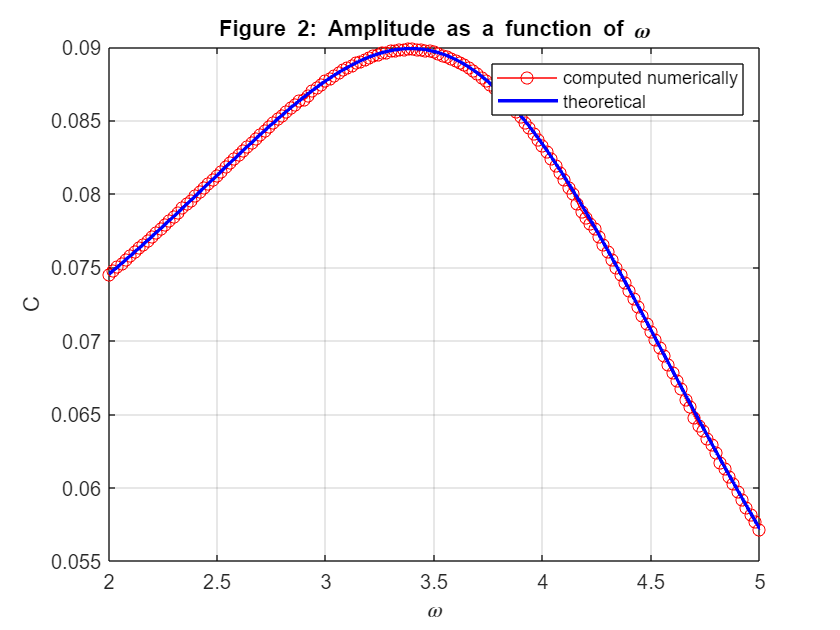

LAB06ex2 % Here I reduce the marker density to 1/2 for better showing the other data

### Part (b)

[maxC,i] = max(C)

maxC = 0.0899

i = 139

theOMEGA = OMEGA(i)

theOMEGA = 3.3800

Value of $\omega$ that gives the practical resonance frequency: 3.38

Coresponding maximum value of the amplitude $C$: 0.0899

### Part (c)

Compute analytically the value of $\omega$ that gives the practical resonance frequency by differentiating $C$:

syms w; assume(w > 0)
C = 1/sqrt((omega0^2-w^2)^2+(c*w)^2)

$$C = \frac{1}{\sqrt{{\left(w^{2}-16\right)}^{2}+9\,w^{2}}}$$

dCdw = diff(C,w)

$$dCdw = -\frac{18\,w+4\,w\,\left(w^{2}-16\right)}{2\,{\left({\left(w^{2}-16\right)}^{2}+9\,w^{2}\right)}^{3/2}}$$

w = solve(dCdw==0)

$$w = \frac{\sqrt{46}}{2}$$

w = double(w)

w = 3.3912

The theoretica value (3.3912) is slightly larger than computed result (3.3800).

### Part (d)

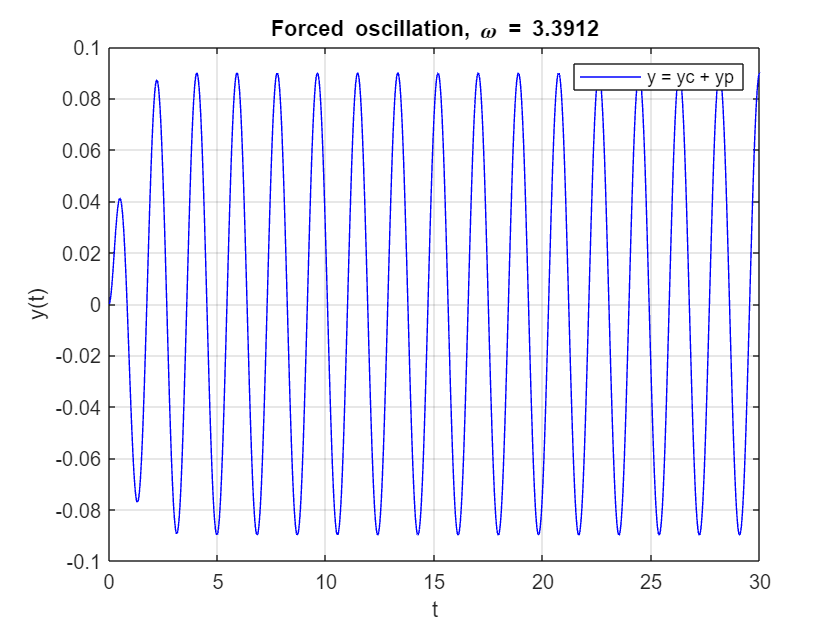

Computed amplitude of forced oscillation = 0.089893
Theoretical amplitude = 0.089893


LAb06ex1_d

Amplitude of the forced oscillation: 0.089893. The amplitude of the forced oscillation found in problem 1 is smaller, and no other value of $\omega$ could lead to larger amplitude of the solution. 

### Part (e)

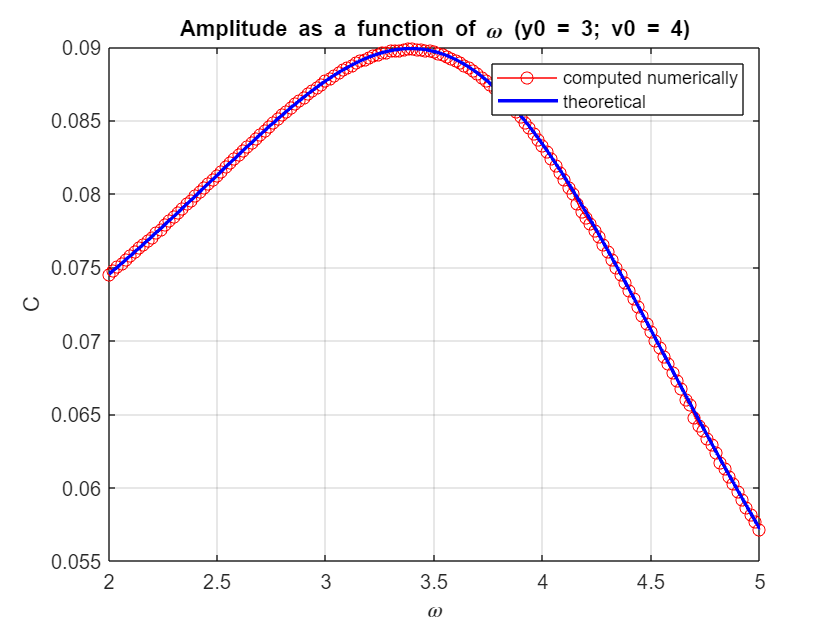

LAB06ex2_e


$$C=\;\frac{1}{\sqrt{\left(\omega_0^2 +\omega^2 {\left.\right)}^2 +c^2 \omega^2 \right.}}$$


The amplitude of the forced oscillation,  $C$, is never affected by the initial conditions, since they are not parts of the fomula.

# Exercise 3

Set $c=0$ in LAB06ex2.m and run it

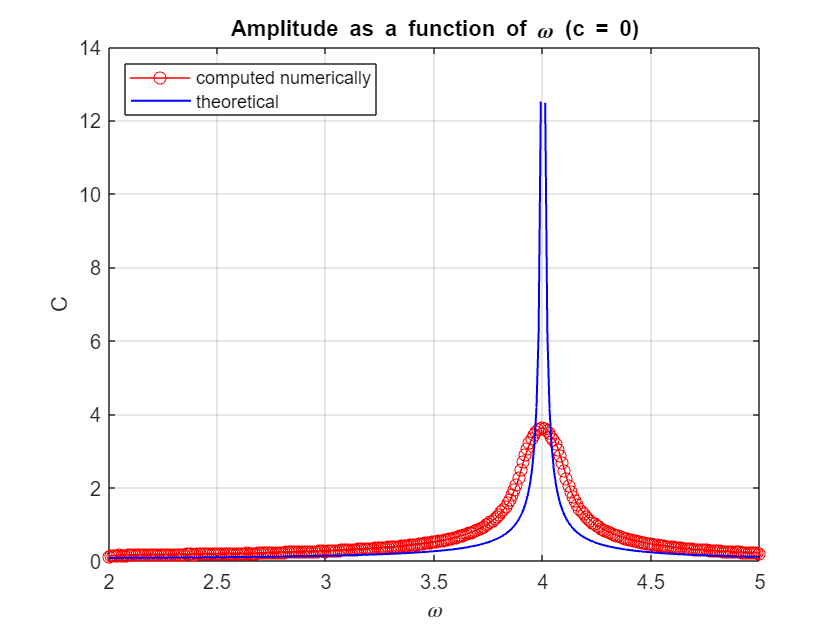

LAB06ex3

### Part (a)

[maxC,i] = max(C)

maxC = 3.6247

i = 201

theOMEGA = OMEGA(i)

theOMEGA = 4

The maximal amplitude is 3.6247. The value of $\omega$ yielding the maximal amplitude in the forced oscillation is 4, and it match the value of $\omega_0$

### Part (b)

% For reference
syms y(t)
ode = diff(y,2)+16*y == cos(4*t);
dy = diff(y,t); cond = [y(0) == 0; dy(0) == 0];
ySol(t) = dsolve(ode,cond); ySol = simplify(ySol) % (F/2*w)*t*sin(w*t) = (1/2*4)*t*sin(4*t)

$$ySol(t) = \frac{t\,\sin\left(4\,t\right)}{8}$$

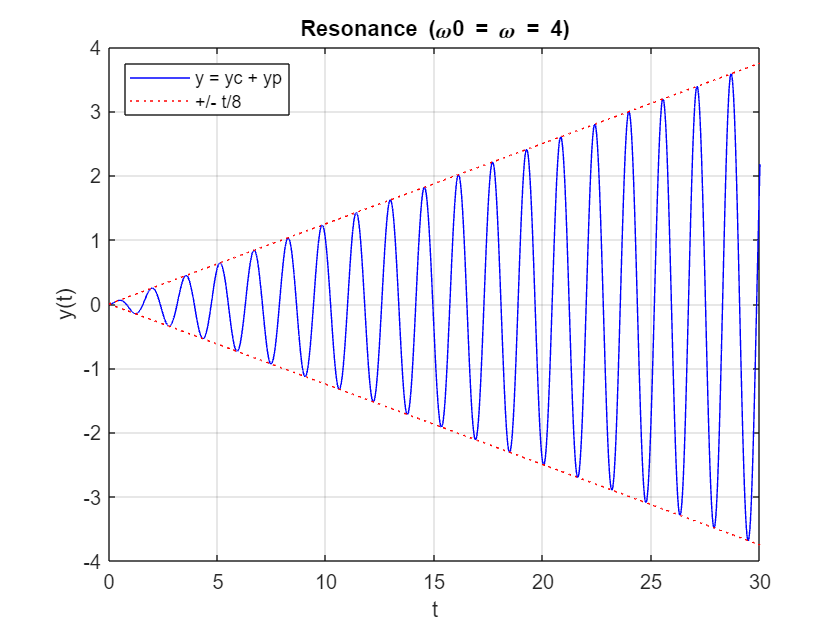

Computed amplitude of forced oscillation = 3.6326
Theoretical amplitude = Inf


LAB06ex3_b

The amplitude is inceeasing linearly and endless with the time.

# Exercise 4

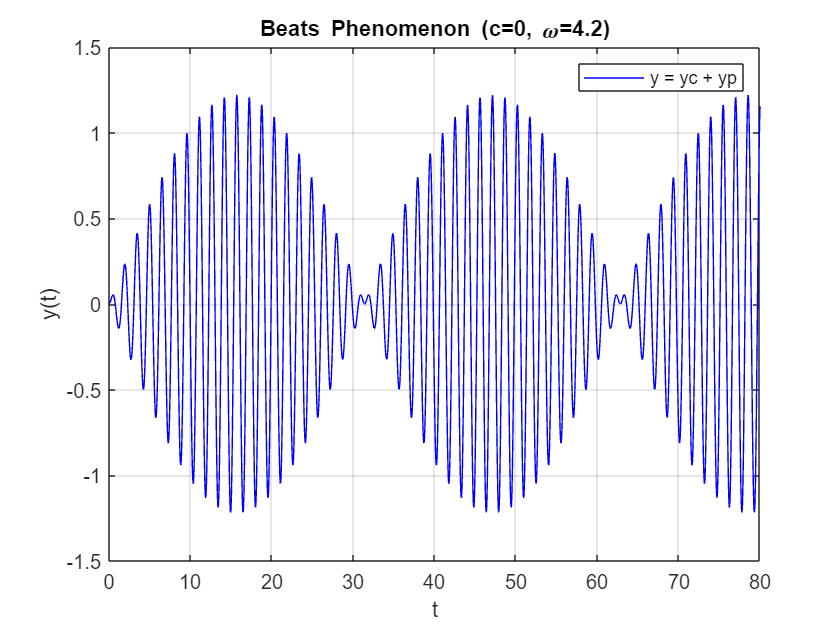

LAB06ex4

### Part (a)

Define the "envelope" functions $A$ and $-A$ in LAB06ex4.m

type LAB06ex4_a.m

clear all;
omega0 = 4; c = 0; omega = 4.2; 
param = [omega0,c,omega]; 
t0 = 0; y0 = 0; v0 = 0; Y0 = [y0;v0]; tf = 80;
options = odeset('AbsTol',1e-10,'relTol',1e-10); 
[t,Y] = ode45(@f,[t0,tf],Y0,options,param); 
y = Y(:,1); v = Y(:,2); 

C = abs(1/(omega0^2-omega^2));
A = 2*C*sin(0.5*(omega0-omega)*t);

figure 
plot(t,y,'b-'); xlabel('t'); ylabel('y(t)'); grid on; 
hold on; plot(t,A,'r-',t,-A,'g-')
title("Envelope Function: A = 2Csin(0.5(\omega0-\omega)t), C=|1/(\omega0^2-\omega^2)|")
legend("y = yc + yp","A","-A")


%----------------------------------------------------------------
function dYdt = f(t,Y,param) 
y = Y(1); v = Y(2); 
omega0 = param(1); c = param(2); omega = param(3);
dYdt = [ v ; cos(omega*t)-omega0^2*y-c*v ];
end


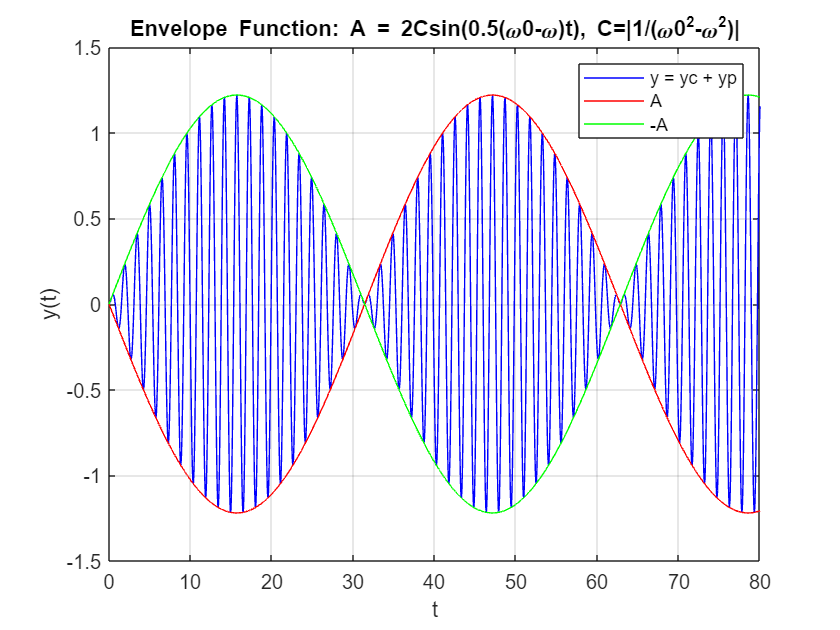

LAB06ex4_a

### Part (b)

Period of the rapidly oscillating function:

T = 4*pi/(omega0+omega)

T = 1.5325

### Part (c)

Length of beats:

LB = 2*pi/abs(omega0-omega)

LB = 31.4159

### Part (d)

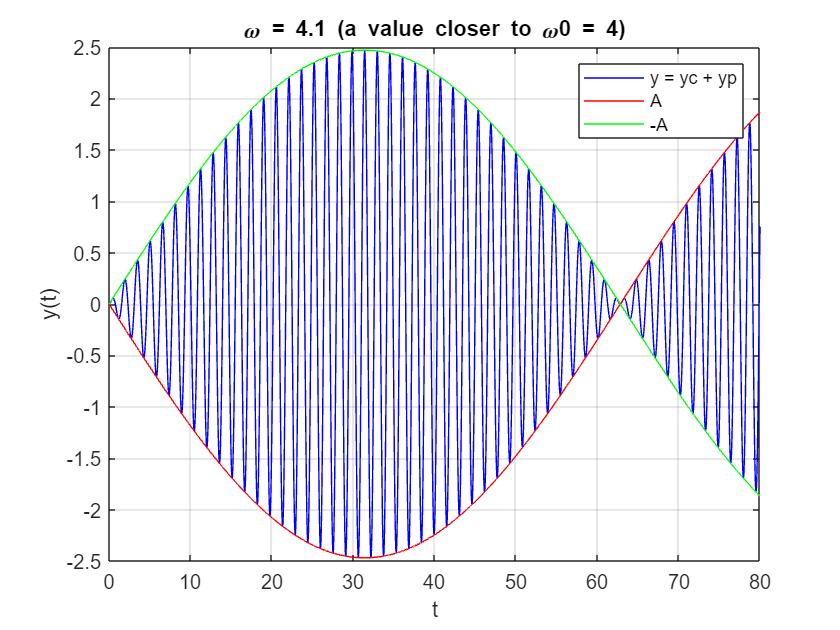

LAB06ex4_d1

T = 4*pi/(omega0+omega)

T = 1.5514

LB = 2*pi/abs(omega0-omega)

LB = 62.8319

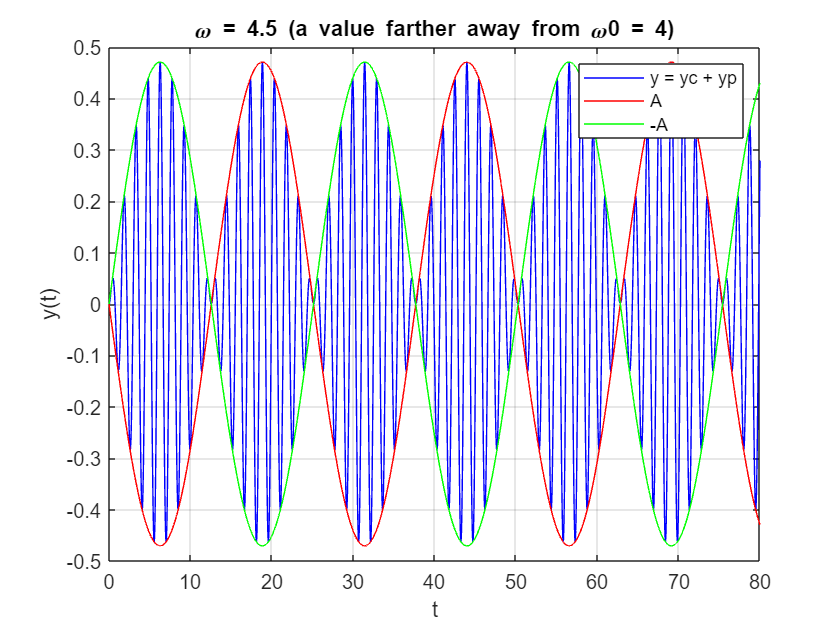

LAB06ex4_d2

T = 4*pi/(omega0+omega)

T = 1.4784

LB = 2*pi/abs(omega0-omega)

LB = 12.5664

T1 = array2table(horzcat([1.5325, 1.5514, 1.4784]',[31.4159, 62.8319, 12.5664]', [4.2-4, 4.1-4, 4.5-4]'));
T1.Properties.VariableNames(1:3) = {'Period','Length of Beats','|w0-w|'}

T1 = 3×3 table
    Period    Length of Beats    |w0-w|
    ______    _______________    ______
    1.5325        31.416          0.2  
    1.5514        62.832          0.1  
    1.4784        12.566          0.5  

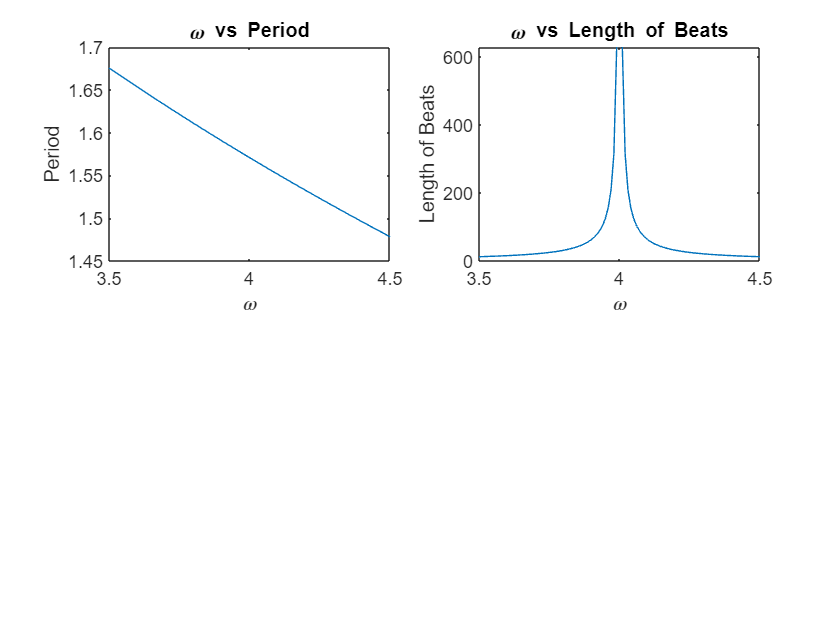

% For W0 = 4
subplot(2,2,1)
omega = 3.5:0.01:4.5; T = 4*pi./(4+omega);
plot(omega,T); title('\omega vs Period'); xlabel("\omega"); ylabel("Period")
subplot(2,2,2)
LB = 2*pi./abs(4-omega);
plot(omega,LB); title('\omega vs Length of Beats'); xlabel("\omega"); ylabel("Length of Beats")

The period will decrease as $\omega $ gets farter away from $\omega_0$ if $\omega $ > $\omega_0$ but  increase as $\omega $ gets farter away from $\omega_0$ if $\omega $ < $\omega_0$. On the other hand, the length of beats will decrease rapidly as $\omega $ gets farter away from $\omega_0$.

### Part (e)

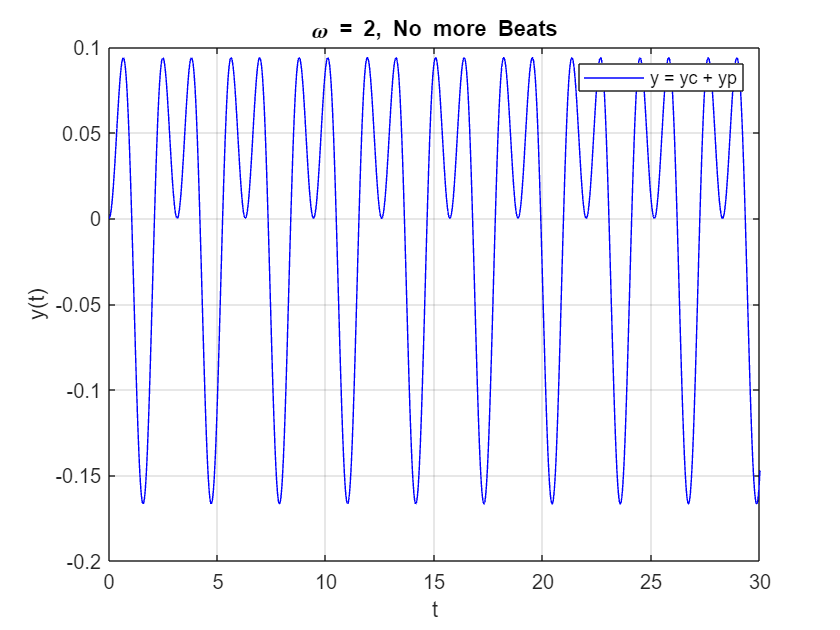

LAB06ex4_e

The beats phenomemon seems disappear probably because $\omega $ gets too farter away from $\omega_0$.

% For reference
syms y(t)
ode = diff(y,2)+16*y == cos(4.2*t);
dy = diff(y,t); cond = [y(0) == 0; dy(0) == 0];
ySol(t) = dsolve(ode,cond); ySol = simplify(ySol)

$$ySol(t) = \frac{25\,\cos\left(4\,t\right)}{41}-\frac{25\,\cos\left(\frac{21\,t}{5}\right)}{41}$$

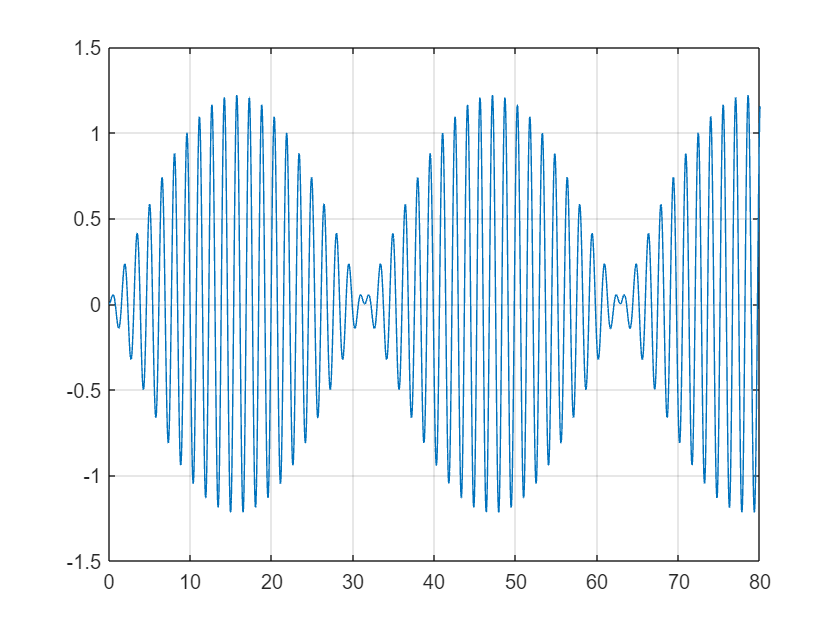

figure; fplot(ySol,[0 80]); ylim([-1.5 1.5]); grid on

syms y(t)
ode = diff(y,2)+16*y == cos(2*t);
dy = diff(y,t); cond = [y(0) == 0; dy(0) == 0];
ySol(t) = dsolve(ode,cond); ySol = simplify(ySol)

$$ySol(t) = -\frac{{\sin\left(t\right)}^{2}\,\left(4\,{\sin\left(t\right)}^{2}-3\right)}{6}$$

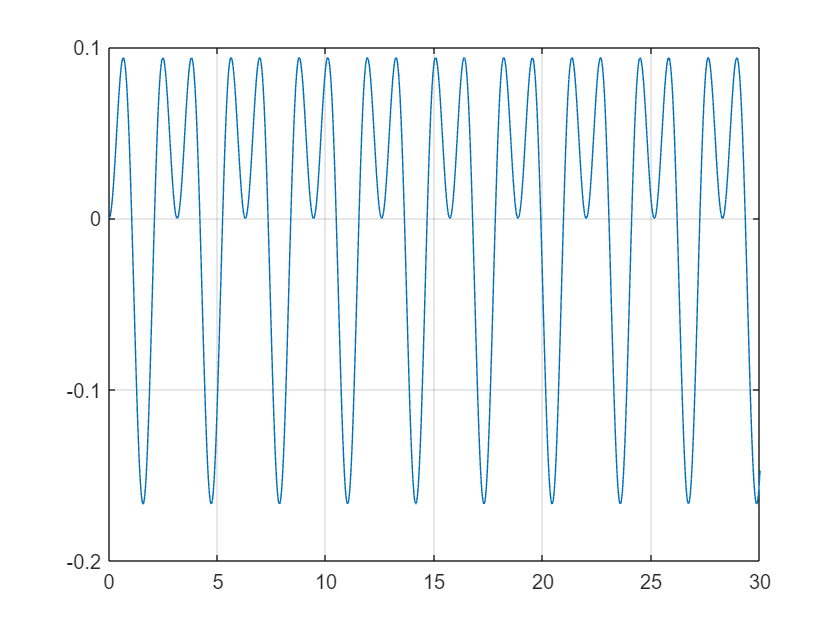

figure; fplot(ySol,[0 30]); ylim([-.2 .1]); grid on